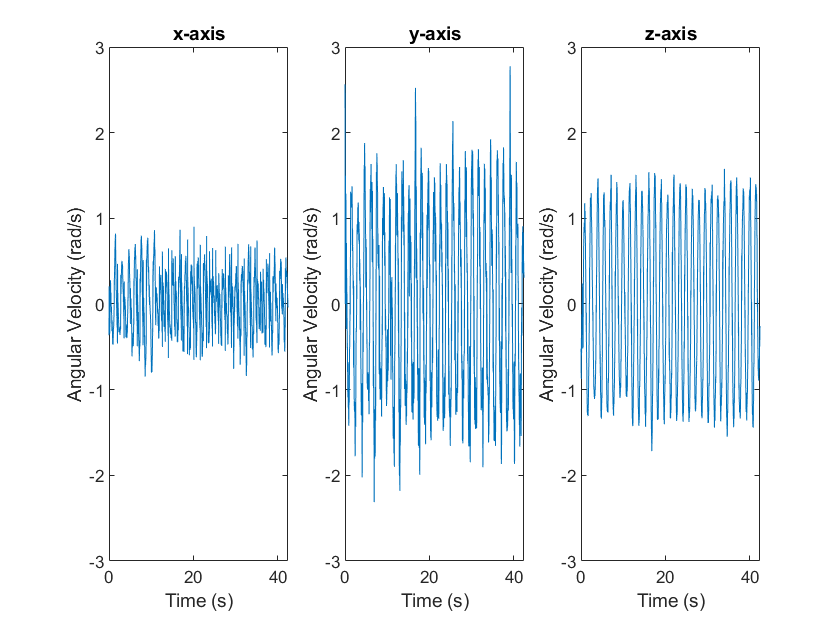

% Screen facing away from skin, phone in readable orientation
% sampling rate = 100 Hz
[MotionData] = ParseMatlabApp('data/trial_80bpm.mat');

% sanity check to make sure that data looks good - plotting AngVel v. time
% notice sinusoidal behavior of z-axis, 40 cycles/min (80 bpm)
% 80 bpm was about z-axis, 60 bpm was about y-axis bc phone slipped a bit
makeAccelerometerPlots([MotionData.t_AngVel,MotionData.AngVel])

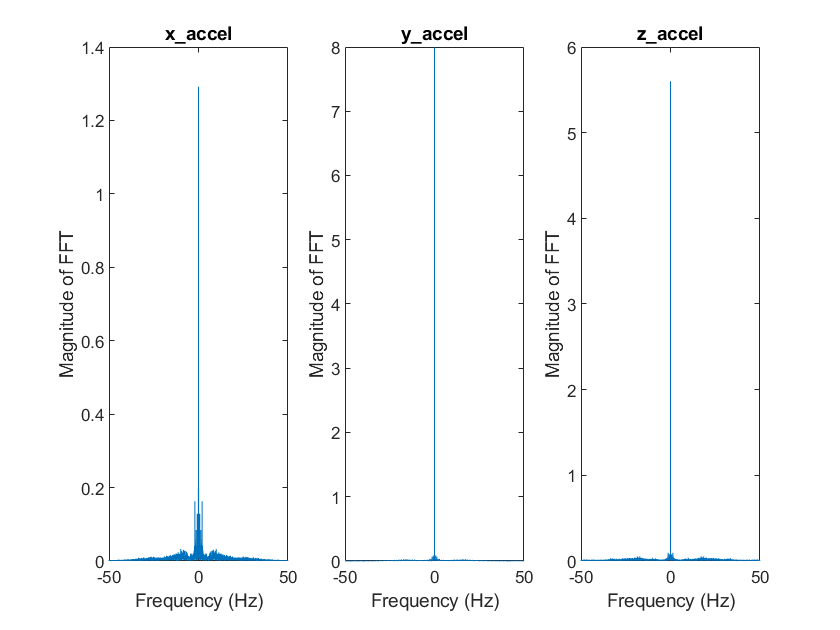

% Frequency from acceleration - not super helpful
fs = 100;           % Hz
x_accel = MotionData.Accel(:,1);
y_accel = MotionData.Accel(:,2);
z_accel = MotionData.Accel(:,3);

clf;
subplot(1, 3, 1);
make_freq_plot(x_accel, fs);          % this is based on acceleration
title("x\_accel");
subplot(1, 3, 2);
make_freq_plot(y_accel, fs);          % this is based on acceleration
title("y\_accel");
subplot(1, 3, 3);
make_freq_plot(z_accel, fs);          % this is based on acceleration
title("z\_accel");

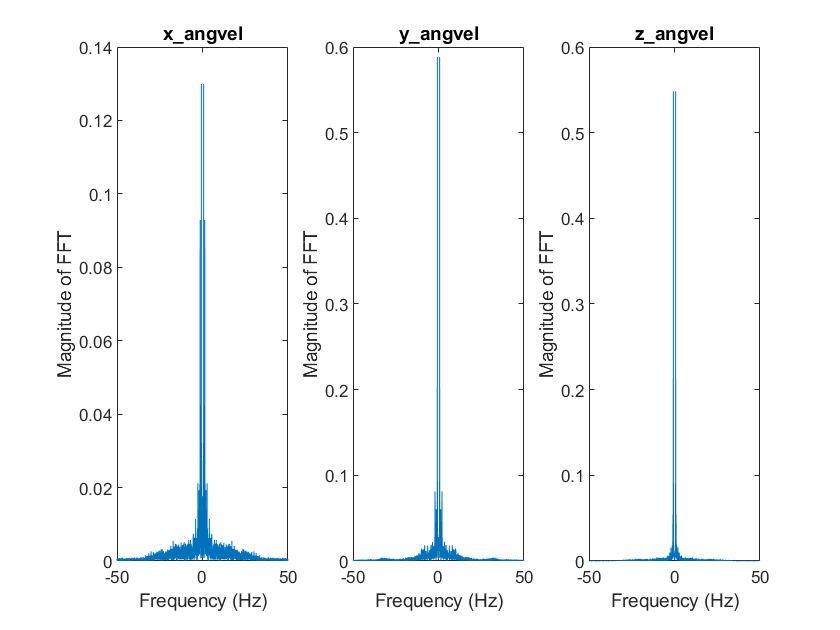

% Frequency from angular velocity - notice motion about z-axis
fs = 100;           % Hz
x_angvel = MotionData.AngVel(:,1);
y_angvel = MotionData.AngVel(:,2);
z_angvel = MotionData.AngVel(:,3);

clf;
subplot(1, 3, 1);
make_freq_plot(x_angvel, fs);
title("x\_angvel");
subplot(1, 3, 2);
make_freq_plot(y_angvel, fs);
title("y\_angvel");
subplot(1, 3, 3);
% figure()
primary_freq = make_freq_plot(z_angvel, fs);
% sweeps_per_min = primary_freq * 60 * 2
title("z\_angvel");

% the two peaks at z_angvel show that we are moving at a constant angular
% velocity back and forth
% Hz of max peak -> conversion -> bpm/2 = sweeps/min
% Hz * 60 * 2 = bpm

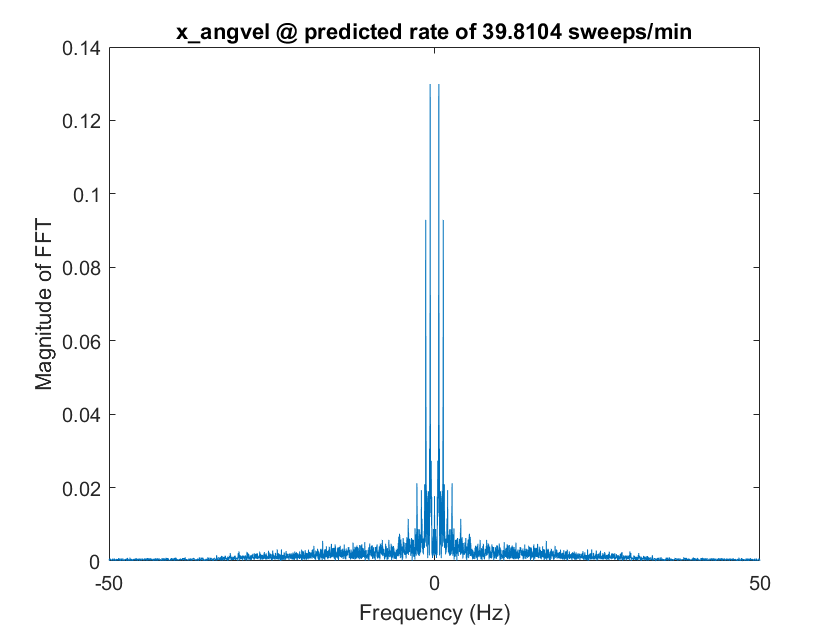

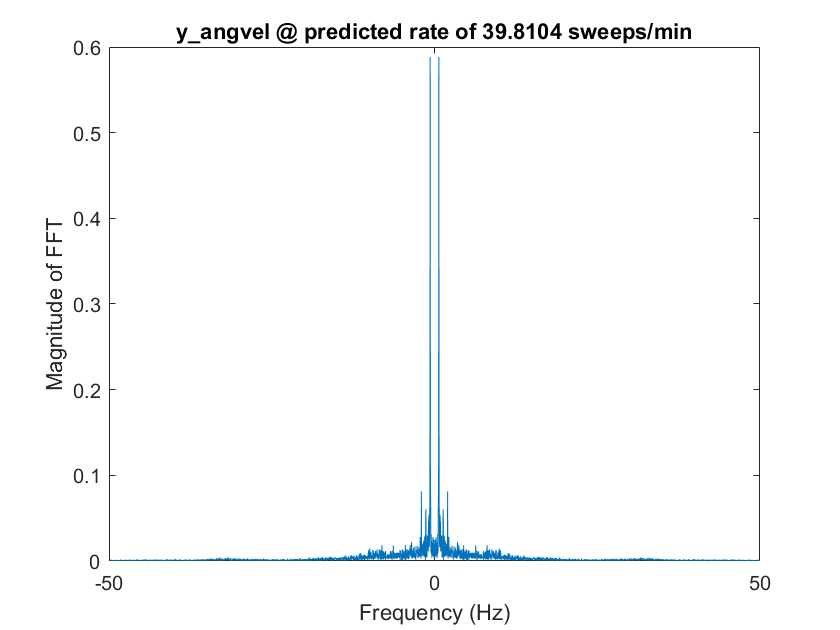

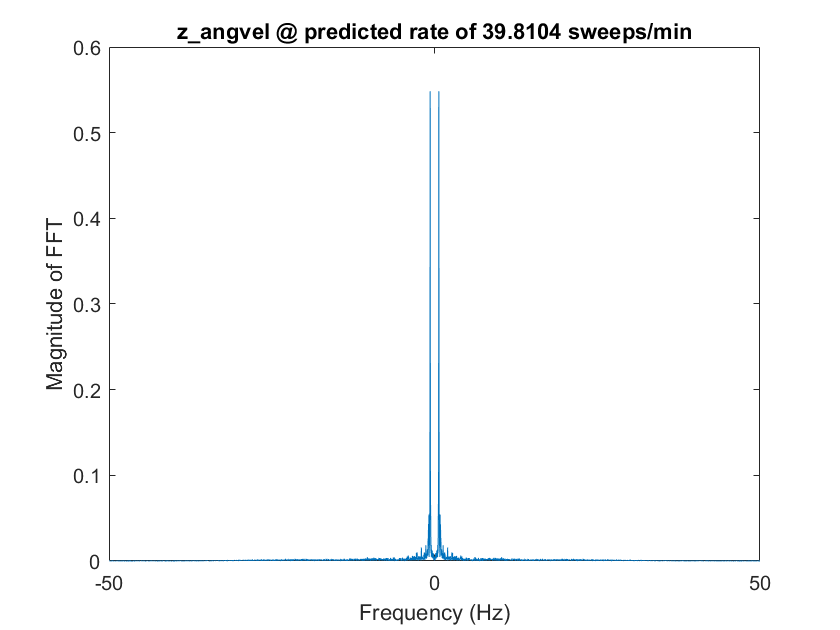

getSweepRate('data/trial_80bpm.mat');

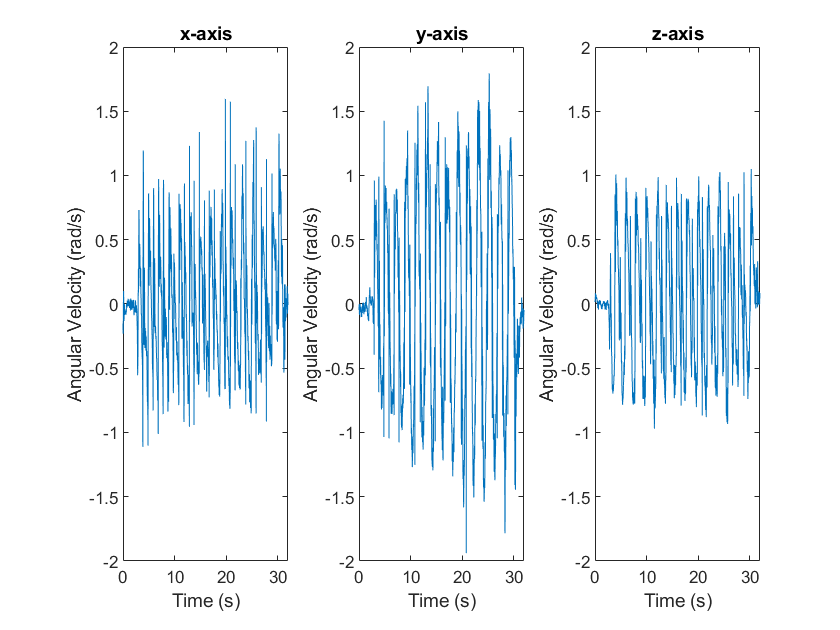

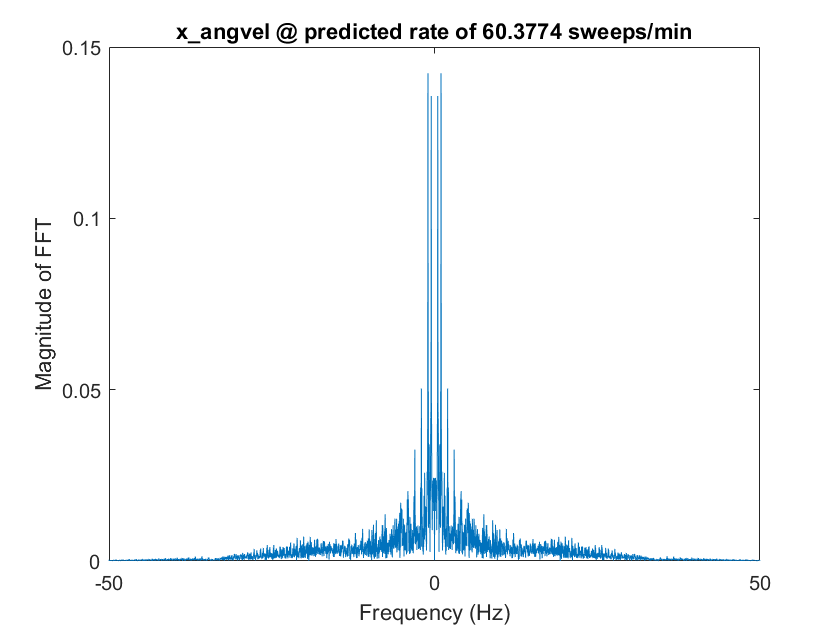

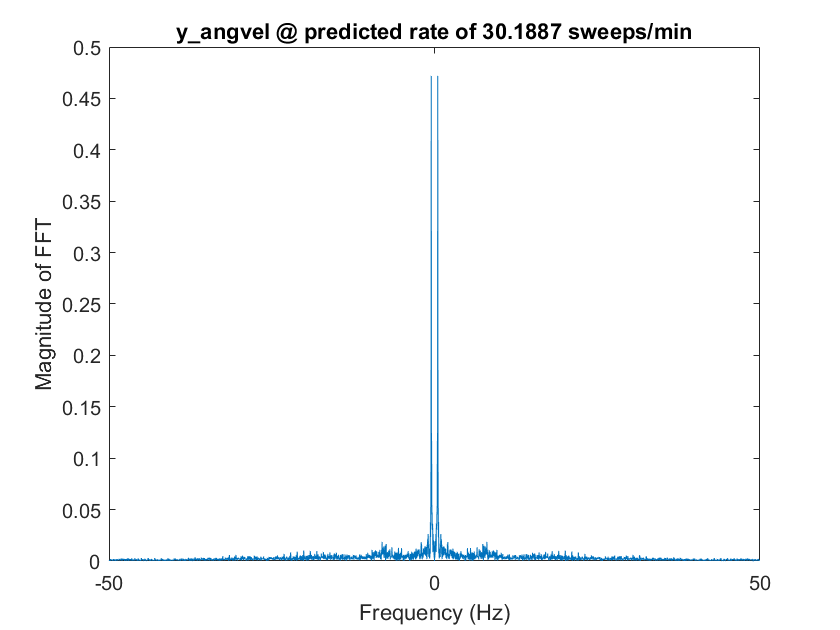

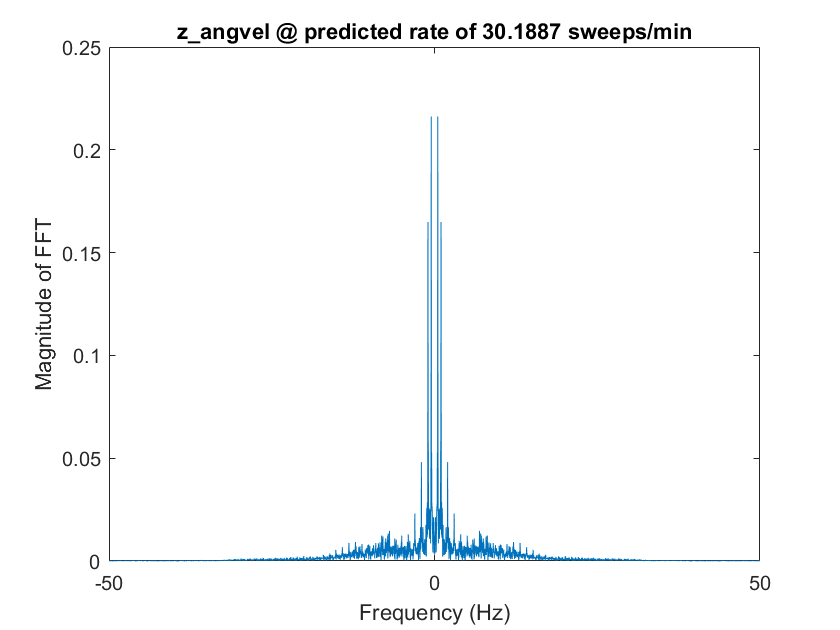

getSweepRate('data/trial_60bpm.mat');

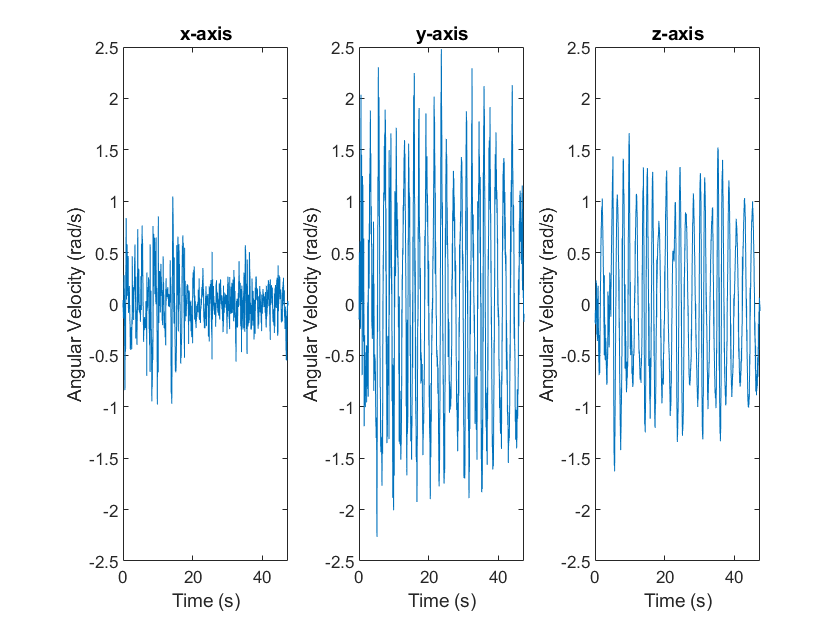

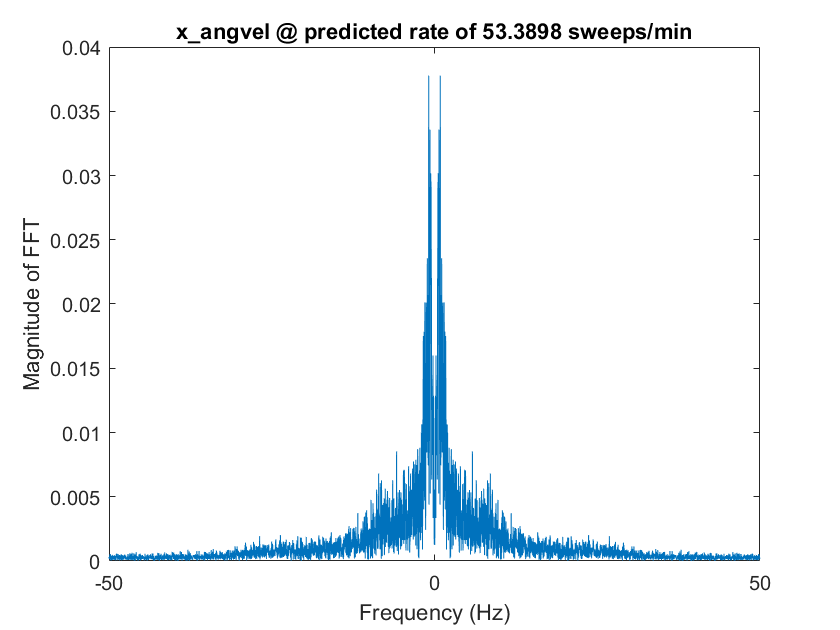

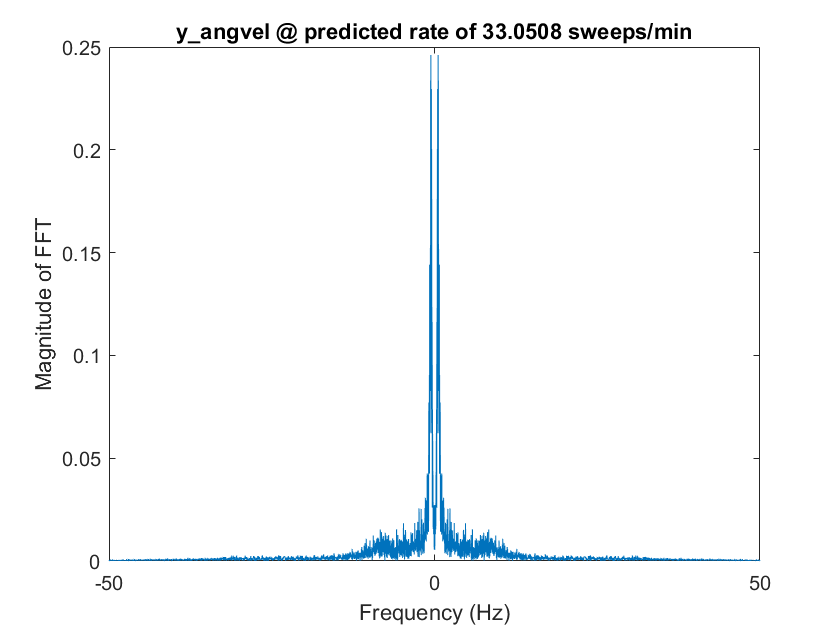

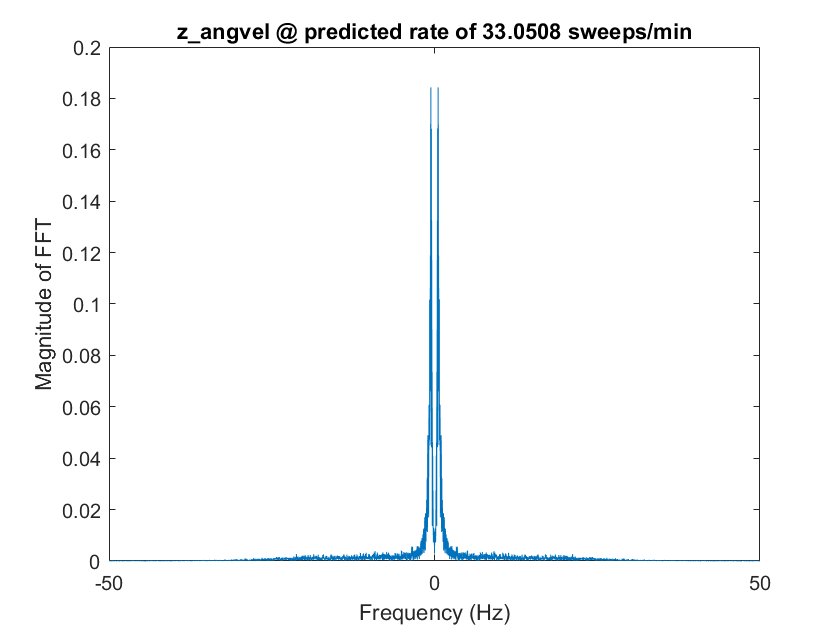

getSweepRate('data/trial_bad.mat');